% Suppress useless warnings:
warning('off', 'Ident:dataprocess:idinput7'); % prbs sequence length warning

% Bode plot options for later
bodeopts = bodeoptions('cstprefs');
bodeopts.Grid = 'on';

bode_no_phase = bodeopts;
bode_no_phase.PhaseVisible = 'off';

% Set a flag so that other scripts that use values provided here can detect 
% whether this script has run and run it if necessary spo
QUAD_COPTER_MLX_RAN = true;

# VRFT Control Algorithm for a Quad Copter Platform

Normally to perfrom VRFT on a platform we would have a set of input-output data and an Idea of a reference model to use. I have neither. I should receive IO data soon but I still won't have any idea about the reference models to use. For a sensitive application such as this the choice of the reference models is essential, a mistaken choice will make the platform unstable and the control performance terrible. 

Instead we will work backwards. First we write the model from the information contained in the thesis, then calculate the complimentary sensitivity function based on the known controllers. This will become our reference model. 

We will use the model we wrote to generate output data from a PRBS input and use that to perform the VRFT on the plant. The controllers we obtain this way should be quite close to the original controllers. At a later time we might try to make the reference models faster and train a new controller with VRFT. 

Our first step now is to build the physical model.

## Building the Physical Model of the Pitch

Since we don't have access to real measurements yet we need to build the physical model to generate ou input - ouput data sets. The thesis provides us with enough information to do this.

The physical model of the system is: 


$$I_n \dot{\omega}_b + \omega_b \times \left( I_n \omega_b \right) = M_{Damp} + M_{props} \\
\qquad \qquad \qquad \quad \dot{\Theta} = q$$


Before going any further we need to calculate $I_{yy}$, $\frac{\partial M}{\partial q}$ and $\frac{\partial M}{\partial u}$. Whilst $I_{yy}$ and $\frac{\partial M}{\partial q}$are provided as estimated values, $\frac{\partial M}{\partial u}$ isn't. The grey box estimation procedure used to estimate the first two values only has two equations and can only estimate two variables. This leaves two options:

-  use the guessed value of $15 \cdot 10^{-3}\ Nms$

- Estimate it using equation 6.22 (p76) however this requires data that I have not been able to locate in the paper. The script file `dM-du-estimation.mlx` attempts to do this.  

Here we will use the guessed value. 

% Using estimated data from Table 6.2 (p79) for Iyy and dM_q
Iyy = 34.7e-3;   % kg m^2
dM_q = -46.3e-3; % N m s

% Using guess from equation 6.26 (p76) for dM_u
dM_u = 15e-3;    % Nms

And the corresponding state space form considering the state vector $x = \left[\ q \ \Theta\ \right]^T $ is:

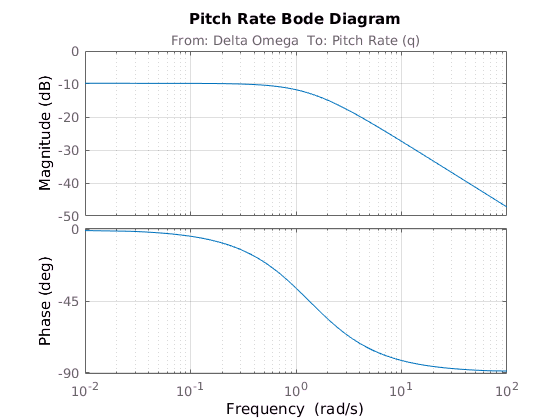

A = [
    1 / Iyy * dM_q,  0;
    1                0;
];

B = [1 / Iyy * dM_u; 0];
C = [1 0];
D = 0;

PitchRateModel = ss(A, B, C, D, ...
    'InputName', 'Delta Omega', 'OutputName', 'Pitch Rate (q)');

% PitchRateModel is also provided in tf form to give convenient access to the
% numerator and denominator to the Simulink Model.
PitchRateModel_tf = tf(PitchRateModel);

figure();
    bode(PitchRateModel);
    title('Pitch Rate Bode Diagram');
    grid on;

A brief comparison with figure 6.5 seems to show that this is a correct implementation of the model.

## The Original Controllers

We do not have standalone reference models at the moment. To begin with we can generate reference models from the known data. We will simply calculate the complementary sensitivity of the inner and outer loops and use thoses as reference models. 

With this approach the optimal controllers should be quite close to the $H_\infty$ controllers from the paper. At a later stage we might try to make faster controllers. 

As shown above the pitch control loop uses an inner PID controller and an outer PD controller. $K_P
$, $K_I$ and $K_D$ are tuned by the $H_{\infty}$ control law. $T_f$ was fixed manually beforehand. The outer controller is based on attitude feedback ($\Theta \rightarrow \Theta_0$) whilst the inner controller is based on angular rate feedback ($q \rightarrow q_0$). The PID parameters are given in table 7.1 (p87).

Tf = .01; % cf. p87 (Bottom right)

% The controllers specified in the thesis are the other way around. I think that this
% is a mistake. The PD fits betters inside than outside.
% Note: The constants in table 7.1 (p87) are wrong. The ones used here are correct !
R2 = pid(.3, 0, .3, Tf);         % Inner
R1 = pid(.05, 1.61, .00512, Tf); % Outer

% For clarity we rename the controllers:
%   - Ri is the inner controller 
%   - Ro is the outer controller
Ri = R1; Ri_tf = tf(Ri);
Ro = R2; Ro_tf = tf(Ro);

The final piece needed to realise the control loop is the mixer matrix. This matrix maps the required thrusts and moments around each axis to the rotational speed of the rotors. 

## The Mixer Matrix

The standard control scheme for a quad-copter uses a nested controller with a PID controller in the inner loop and a PD controller in the outer loop. 

The mixer matrix relates $\Omega_1^2 $, $\Omega_2^2$, $\Omega_3^2$ and $\Omega_4^2$ to the thrust and moments generated by the propellers. The calculations for this section are longer and will not be reported here. You can however find them on my [thesis log](http://thesis.comkieffer.com/modelling-is-like-plumbing.html).

Mixer = dM_u^-1;

## Connecting everything together

We now have all pieces of the puzzle. We just need to wire them together.

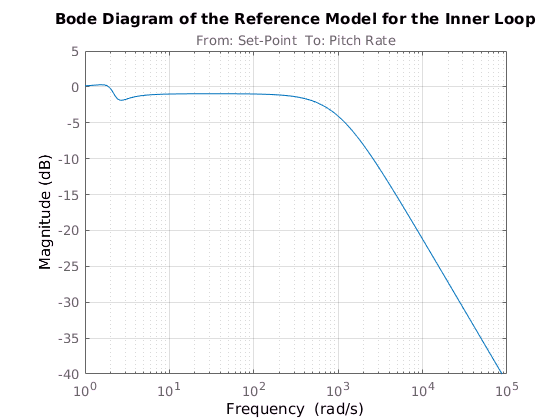

InnerLoop = loopsens(PitchRateModel * Mixer, Ri);

InnerReferenceModel = tf(InnerLoop.Ti);
InnerReferenceModel.InputName = 'Set-Point';
InnerReferenceModel.OutputName = 'Pitch Rate';

figure();
    bode(InnerReferenceModel, bodeopts);
    title('Bode Diagram of the Reference Model for the Inner Loop');

There is no plot I can use in the thesis to check that this reference model is correct. I have no idea what how wrong it is. 

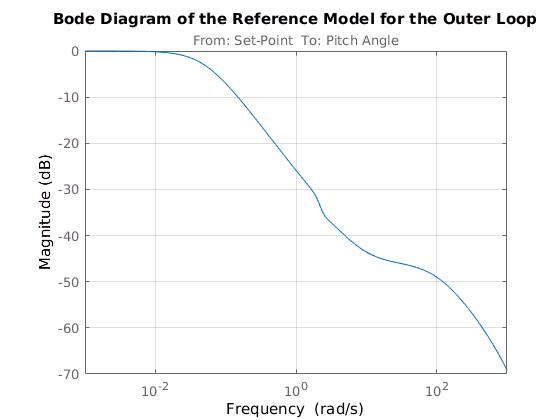

integrator = tf(1, [1 0]);
OuterLoop = loopsens(integrator * InnerReferenceModel, Ro);

OuterReferenceModel = tf(OuterLoop.Ti);
OuterReferenceModel.InputName = 'Set-Point';
OuterReferenceModel.OutputName = 'Pitch Angle';

figure();
    bode(OuterReferenceModel, bodeopts);
    title('Bode Diagram of the Reference Model for the Outer Loop');
    xlim([10^-3 10^3]);


% figure()
%     pzmap(OuterReferenceModel);
%     title({'Detail view of the Poles & Zeros of', 'the Outer Reference Model (M_o)'})
%     xlim([-10, 1])

The only figure I can find in the thesis to validate this is figure 7.5. It looks nothing like this. This is a problem. 

## Attempting to validate the model

Figure 6.6 shows the output of the system being fed a PRBS sequence. We will try to recreate it to validate the model. We will also be able to use this data later on when we perform the actual VRFT.

The constants needed to generate the PRBS are not specified and until I have these the data might not be accurate.  The values chosen here are "best-guess" attempts at replicating the graphs in figure 6.6 (p80).

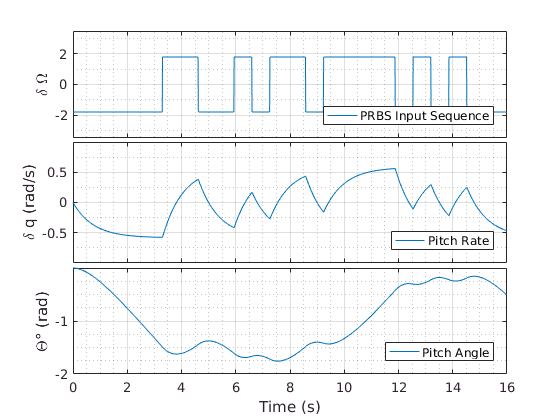

N = 1600;          % Eyeballed to make the data sequence have the right size.
bw = .015;         % rad/s - Chosen more or less at random (bandwidth)
Ts = .01;          % s - The FCU runs at 100Hz so I assume that this is the sample time
signal_peak = 1.8; % rad/s - Eyeballed from figure 6.6a (p(80)

time_vec = (0:(N-1)) * Ts; 

in = idinput(N, 'prbs', [0 bw], [-signal_peak, signal_peak]);

yi = lsim(PitchRateModel, in, time_vec);
yo = lsim(integrator, yi, time_vec);

fh = figure();
    subplot 311;
        plot(time_vec, in);
        legend('PRBS Input Sequence', 'location', 'SouthEast');
        ylabel('\delta \Omega'); grid minor; ylim([-3.5 3.5]);
    subplot 312;
        plot(time_vec, yi);
        legend('Pitch Rate', 'location', 'SouthEast');
        ylabel('\delta q (rad/s)'); grid minor;
        ax = gca; ax.YTick = [-0.5 0 0.5];
    subplot 313;
        plot(time_vec, yo);
        legend('Pitch Angle', 'location', 'SouthEast');
        ylabel('\Theta° (rad)'); xlabel('Time (s)'); grid minor;

condense_subplots('tight', true);

At a glance, I have noidea what units $\delta \Omega$ is in. I assume `rpm` but I have no actual idea . Same goes for the pitch angle, is `°` or  `rad `? 

## Testing our models

The thesis has a couple of graphs we can use to try to check the validity of our model. The sensitivity functions and the simulation graphs. 

Following the naming conventions of the thesis we have:    

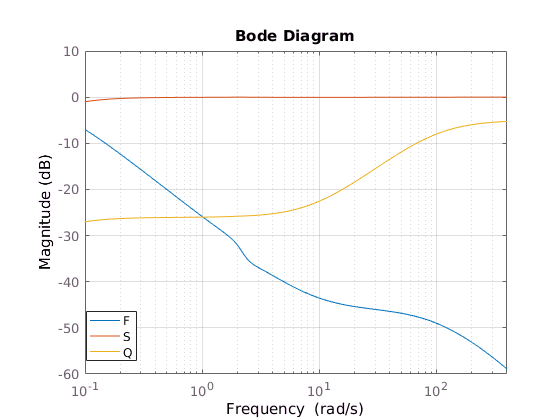

Gq = tf(PitchRateModel);
Fin = (Gq * Mixer * Ri) / (1 + Gq * Mixer * Ri);
L = integrator * Fin * Ro;

F =  L / (1 + L);
S =  1 / (1 + L);
Q = R2 / (1 + L);

figure()
    bode(F, S, Q, bode_no_phase)
    xlim([10^-1, 20^2]);
    legend('F', 'S', 'Q', 'location', 'southWest');

Assuming that figure 7.7 (p91) is showing the Complementary, Sensistivity and control sensitivity functions then I am waaaaay off base. That diagram shows stuff that has a single pole or zero in s = 1. Clearly my results do not match.

Another figure we can use is figure 7.13 (p96). This figure shows the output of the plant given an inut signal that doesn't look too hard to rebuild.

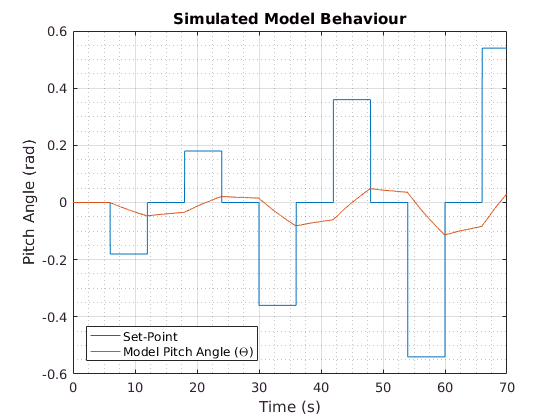

step_size = .18;     % Rough guess from the figures
step_duration = 600; % Estimated 6s per state, 100 samples per second
time_step = .01;     % 100 samples/sec. Extrapolated from FCU freq (100Hz)
test_time_vec = time_step * [0:(70/time_step)]'; 

base = ones(1, step_duration);
test_theta_set_point = [
    base * 0, base * -1 * step_size, base * 0, base * step_size, base * 0, ...
    base * -2 * step_size, base *  0, base * 2 * step_size, base * 0,      ...
    base * -3 * step_size, base *  0, base * 3 * step_size, base * 0,      ...
]';

% Crop the input sequence to the size of the time vector
test_theta_set_point = test_theta_set_point(1:length(test_time_vec));

% Build a |timeseries| object from the input data so that we can pass it into
% Simulink as an input signal
test_input_ts = struct('time', test_time_vec, ...
    'signals', struct('values', test_theta_set_point, 'dimensions', 1));

% Simulate and plot !
test_theta = lsim(OuterReferenceModel, test_theta_set_point, test_time_vec);

figure();
    plot(test_time_vec, test_theta_set_point, test_time_vec, test_theta);
    title('Simulated Model Behaviour');
    legend('Set-Point', 'Model Pitch Angle (\Theta)', ...
        'location', 'southWest');
    ylabel('Pitch Angle (rad)'); xlabel('Time (s)');
    grid minor;

This is starting to look better. The controller is still too slow but at least its trying !

We also have graphs for $q
$ (the inner control variable) and $\delta M$we can try to build as well.

The set-point for the angular rate is simply the output of the outer controller. 

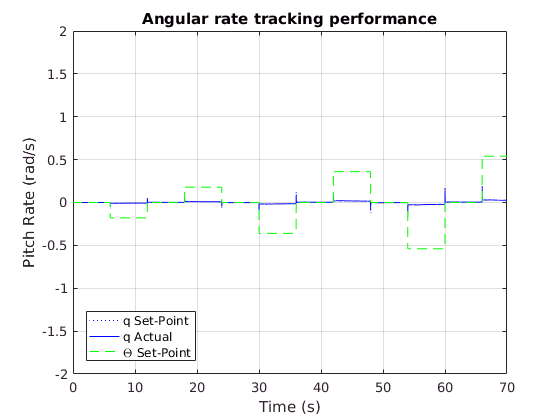

outer_control_sens = Ro / (1 + OuterLoop.Li);

% Generate the inner set point signal (q_0)
test_q_set_point = lsim(outer_control_sens, test_theta_set_point, test_time_vec);

% Produce the actual q signal
test_output_q = lsim(InnerReferenceModel, test_q_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_q_set_point    , 'b:', ...
         test_time_vec, test_output_q       , 'b'  , ...
         test_time_vec, test_theta_set_point, 'g--'  ...
    );
    legend('q Set-Point', 'q Actual', '\Theta Set-Point', 'location', 'southWest');    
    title('Angular rate tracking performance');
    xlabel('Time (s)'), ylabel('Pitch Rate (rad/s)');
    
    % The set point spikes significantly and obscures some of the actual dynamics of 
    % the signal. To comabt this we reduce the scope of the graph.
    ylim([-2, 2]);

The angular rate is looking good but it is still completely outside of the range from the paper. Their data has angular rates between  1 and -1, our set-point is between 5 and -5. However if we look at the actual angular rate we see that the system smooths the set point and the actual values of the angular rate are very similar to what is seen in the paper.

Next step is to generate the quad-copter input variable $\delta M$. 

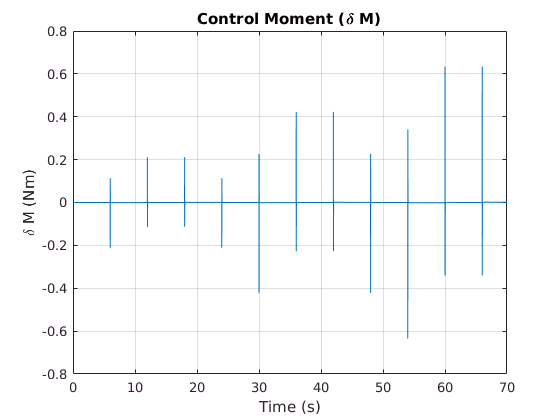

inner_control_sens = Ri / (1 + InnerLoop.Li);

% Generate the control moment (outputs of the inner controller)
test_input_dM = lsim(inner_control_sens, test_q_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_input_dM);
    title('Control Moment (\delta M)');
    xlabel('Time (s)'); ylabel('\delta M (Nm)');    

We can also look at the error in the inner loop:

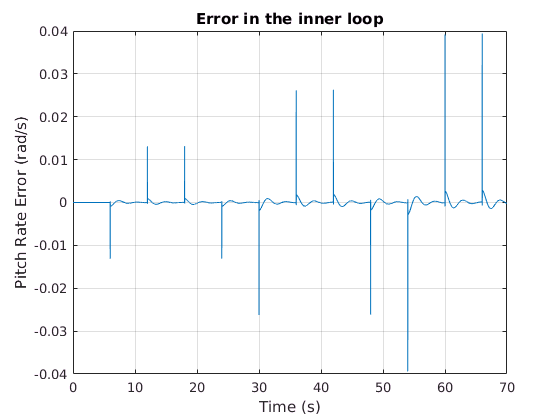

inner_error = test_q_set_point - test_output_q;

figure()
    plot(test_time_vec, inner_error);
    title('Error in the inner loop');
    xlabel('Time (s)'); ylabel('Pitch Rate Error (rad/s)');    

## VRFT - The Inner Loop

We can now be relatively confident that our model is close enough to the truth. Time to apply the VRFT procedure. 

Note: The response of the pitch angle is still too slow. I have no idea why but I'm going to pretend that everything is fine at the moment. 

The reference models we will be using are simply the complementary sensitivity  functions of the two loops. However since VRFT only works on discrete time systems we need to discretize all the systems:

InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);
OuterReferenceModel_dt = c2d(OuterReferenceModel, Ts);

InnerPlant_dt = c2d(PitchRateModel * Mixer, Ts);
OuterPlant_dt = c2d(integrator, Ts);

We have previously generated a set of input output data for the continous time plant. We will use this data as the input to the VRFT procedure.

The first step of the VRFT is to build the inner controller. This wil be a PID controller like the original.


$$C_i(z) = K_{Pi} + K_{Ii} \frac{1}{s} + K_{Di} \frac{s}{1 + sT_f} $$


We will use the same filter constant ($T_f = 0.1
$) that was used to build the initial controllers.

% We separate the proportional and derivative parts of the PID 
InnerControllerClass = [ 1, tf(1, [1 0]), tf([1 0], [Tf 1]) ].';
InnerControllerClass_dt = c2d(InnerControllerClass, Ts);

From here we can apply the VRFt method. We will reuse the PRBS input sequence we generated earlier as the VRFT input however we need to recalculate the outputs to account for the mixer matrix. Neglecting this will result in an error in the static gain of the controller.

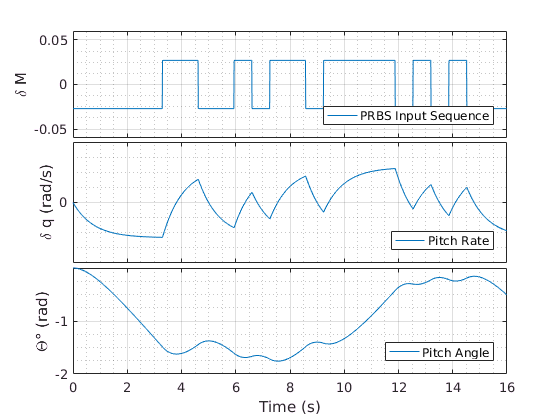

N = 1600;
vrft_time = [0:(N-1)] * Ts; 

in = idinput(N, 'prbs', [0 bw], [-signal_peak / Mixer, signal_peak / Mixer]);
yi = lsim(InnerPlant_dt, in, vrft_time);
yo = lsim(OuterPlant_dt, yi, vrft_time);

figure();
    subplot 311;
        plot(time_vec, in);
        legend('PRBS Input Sequence', 'location', 'SouthEast');
        ylabel('\delta M'); grid minor; ylim([-0.06, 0.06]);
    subplot 312;
        plot(time_vec, yi);
        legend('Pitch Rate', 'location', 'SouthEast');
        ylabel('\delta q (rad/s)'); grid minor;
    subplot 313;
        plot(time_vec, yo);
        legend('Pitch Angle', 'location', 'SouthEast');
        ylabel('\Theta° (rad)'); xlabel('Time (s)'); grid minor;

condense_subplots('tight', true);


[OptimalInnerController, InnerControllerParams] = ...
    VRFT1_ry_theta(in, yi, InnerReferenceModel_dt, InnerControllerClass_dt, [], [], []);
OptimalInnerController.Variable = 'z^-1';

fprintf('The optimal inner controller in PID form is: \n');

The optimal inner controller in PID form is: 


pid(InnerControllerParams(1), InnerControllerParams(2), InnerControllerParams(3), Tf, Ts)


ans =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 2.63, Ki = -0.156, Kd = 0.00468, Tf = 0.01, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PIDF controller in parallel form.



We can now compare the performance of the two controllers:

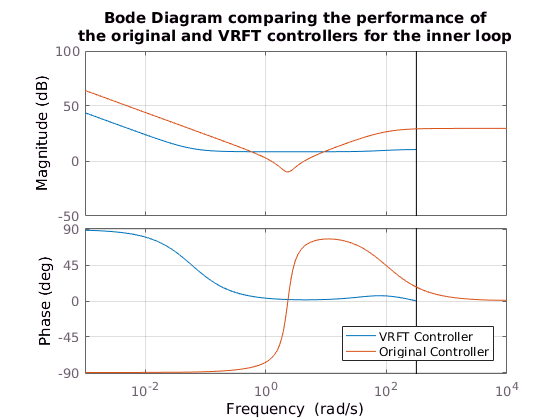

figure()
    bode(OptimalInnerController, Ri);
    grid on; 
    title({'Bode Diagram comparing the performance of', ...
        'the original and VRFT controllers for the inner loop'});
    legend('VRFT Controller', 'Original Controller', ...
        'location', 'SouthEast');

The match is excellent ! Even at high frequencies the phase and magnitude stay extremely close !

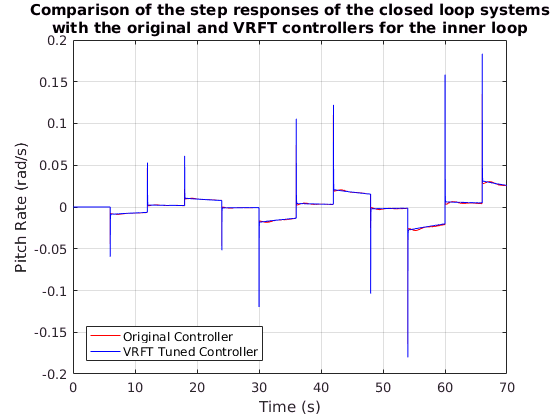

PitchRateModel_dt = c2d(tf(PitchRateModel), Ts);
    
OptimalInnerLoop = loopsens(PitchRateModel_dt * Mixer, OptimalInnerController); 
yi_vrft = lsim(OptimalInnerLoop.Ti, test_q_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_output_q, 'r', test_time_vec, yi_vrft, 'b');
    title({'Comparison of the step responses of the closed loop systems' ...
        'with the original and VRFT controllers for the inner loop'});
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');
    legend('Original Controller', 'VRFT Tuned Controller', ...
        'location', 'southWest');

## VRFT - The Outer Loop

The outer controller is a PD. The controller class is thus: 

OuterControllerClass = [ 1, tf([1 0], [Tf 1]) ].';
OuterControllerClass_dt = c2d(OuterControllerClass, Ts);

We can now perform the VRFT on the outer loop. We already have the reference model but we still have to build the new vritual reference signal. This signal is simply: 


$$r_i(t) = e_i(t) + y_i(t) = C_i^{-1}(z) \ u(t) + y_i(t) 
$$


Where $C_i(z)$ is the inner controller. The reasoning behind this is detailed in my [thesis log](http://thesis.comkieffer.com/pages/cascade-vrft.html).

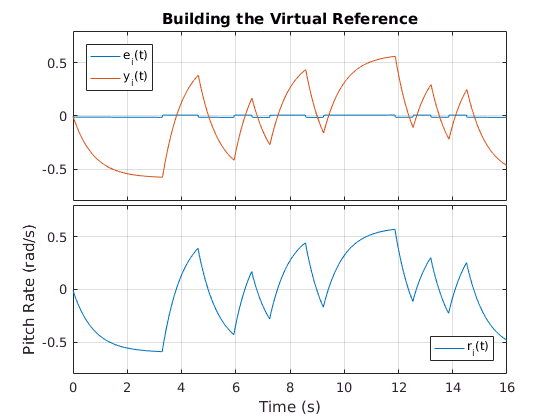

ei = lsim(OptimalInnerController^-1, in, vrft_time); % Inner error signal.
ri = ei + yi;                                        % Virtual Reference signal.

% Verify the results
figure;
    subplot 211;
        plot(vrft_time, ei, vrft_time, yi);
        legend('e_i(t)', 'y_i(t)', 'location', 'northWest');
        title('Building the Virtual Reference'); ylim([-.8, .8]);
    subplot 212;
        plot(vrft_time, ri);
        legend('r_i(t)', 'location', 'southEast'); ylim([-.8, .8]);
        xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');
condense_subplots('tight', true);

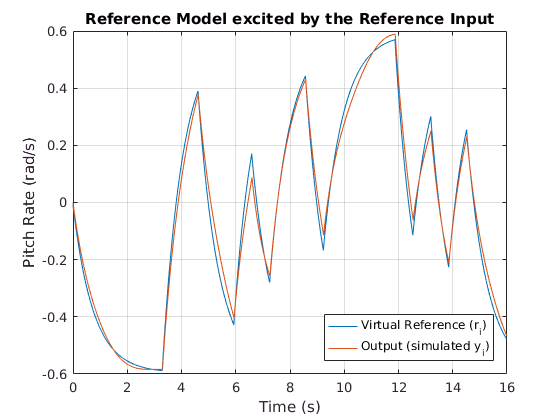


vrft_out = lsim(InnerReferenceModel_dt, ri, vrft_time);
figure;
    plot(vrft_time, ri, vrft_time, vrft_out);
    legend('Virtual Reference (r_i)',  'Output (simulated y_i)', ...
        'location', 'southEast');
    title('Reference Model excited by the Reference Input');
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');

Now that we know that the generated data is good we can move on to the actual VRFT.

[OptimalOuterController, OuterControllerParams] = ...
    VRFT1_ry_theta(ri, yo, OuterReferenceModel_dt, OuterControllerClass_dt, [], [], []);
OptimalOuterController.Variable = 'z^-1';

fprintf('The optimal outer controller in PD form is: \n');

The optimal outer controller in PD form is: 


pid(InnerControllerParams(1), 0, InnerControllerParams(2), Tf, Ts)


ans =
 
                 1     
  Kp + Kd * -----------
            Tf+Ts/(z-1)

  with Kp = 2.63, Kd = -0.156, Tf = 0.01, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PDF controller in parallel form.



Again, we compare the perfomance of the original controller and the PID controller: 

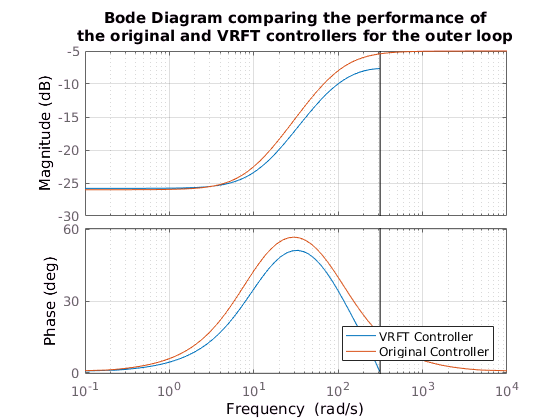

figure()
    bode(OptimalOuterController, Ro);
    grid on; 
    title({'Bode Diagram comparing the performance of', ...
        'the original and VRFT controllers for the outer loop'});
    legend('VRFT Controller', 'Original Controller', ...
        'location', 'SouthEast');

And the closed loop responses using the series of  steps data:

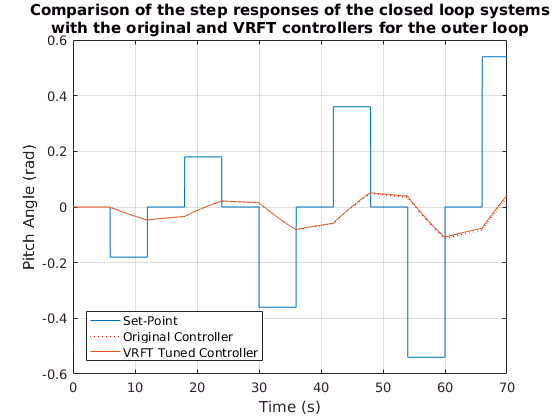

OptimalOuterLoop = loopsens(OuterPlant_dt * OptimalInnerLoop.Ti, OptimalOuterController); 
yo_vrft = lsim(OptimalOuterLoop.Ti, test_theta_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_theta_set_point, ...
         test_time_vec, test_theta, 'r:', test_time_vec, yo_vrft);
    title({'Comparison of the step responses of the closed loop systems' ...
        'with the original and VRFT controllers for the outer loop'});
    xlabel('Time (s)'); ylabel('Pitch Angle (rad)');
    legend('Set-Point', 'Original Controller', 'VRFT Tuned Controller', ...
        'location', 'southWest');